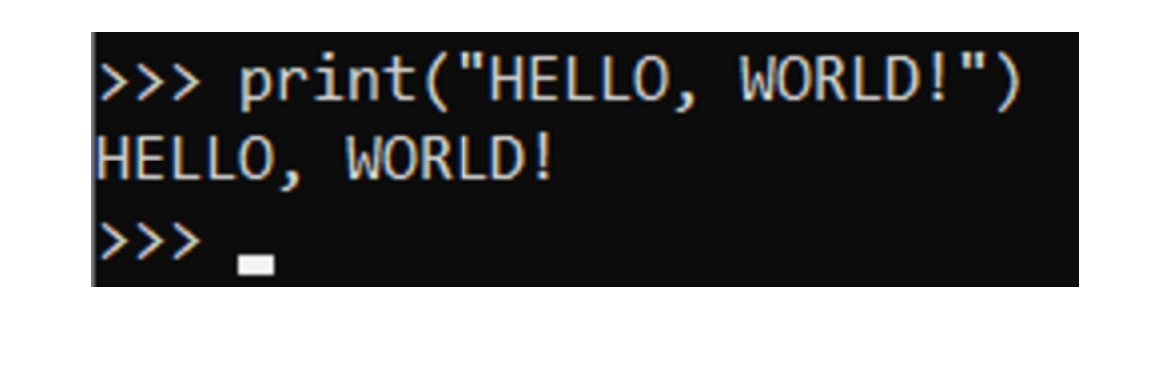

clc;
clear all;
im=imread('D:\Documents\nus\5405-machine vision\project\hello_world.jpg');
imshow(im);

2.sub-image

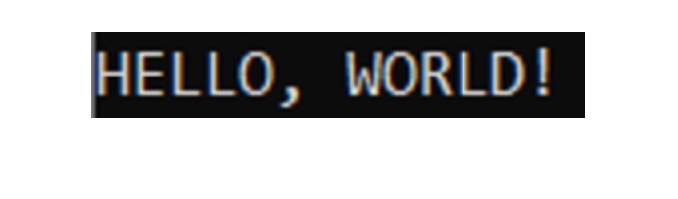

subim=im([1/3*size(im,1):2/3*size(im,1)],:,:);%row 1/3
subim=subim(:,[1:1/2*size(subim,2)],:);%column 1/2
imshow(subim);

3.binary-image

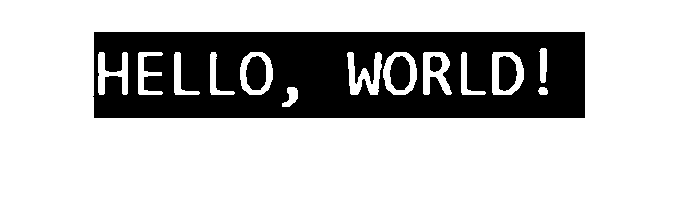

grayim=rgb2gray(subim);

grayim(grayim<100)=0;
grayim(grayim>=100)=1;
imshow(grayim,[0,1]);

4.one-pixel thin

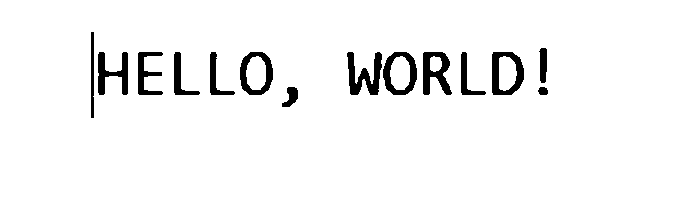

P=1-grayim;%negative
imshow(P,[0,1]);

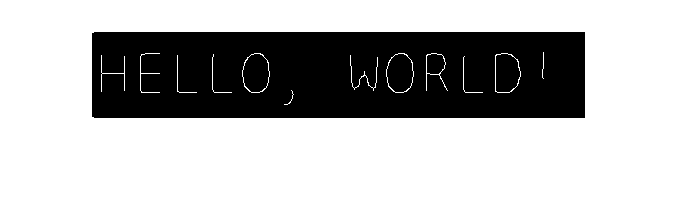


se_search=1;%south-east search
cut = zeros(size(P)); %to be cut
cut = uint8(cut);%white
delete_flag=1;
eightnb=zeros(8);
eightnb = uint8(eightnb);%white
while delete_flag
    delete_flag=0;
  for i=2:size(P,1)-1
      for j=2:size(P,2)-1
          if(P(i,j)==1)%white is background
              continue;
          end
          eightnb=[P(i-1,j),P(i-1,j+1),P(i,j+1),P(i+1,j+1),P(i+1,j),P(i+1,j-1),P(i,j-1),P(i-1,j-1)];
          pairnum=0;
          %determine [0,1] pairs
          for k=1:8           
              if(eightnb(k)==0 && eightnb(mod(k,8)+1)==1)%avoid offset
                  pairnum=pairnum+1;
              end
          end
              %south-east search
              if(se_search==1 && sum(eightnb(:))<=6 && sum(eightnb(:))>=2 && pairnum==1)
                  if(eightnb(1)+eightnb(3)+eightnb(5)>0 && eightnb(3)+eightnb(5)+eightnb(7)>0)
                      cut(i,j)=1;%delete i,j (set to white)
                      delete_flag=1;
                  end
              end
              %north-west search
              if(se_search==0 && sum(eightnb(:))<=6 && sum(eightnb(:))>=2 && pairnum==1)
                  if(eightnb(1)+eightnb(5)+eightnb(7)>0 && eightnb(1)+eightnb(3)+eightnb(7)>0)
                      cut(i,j)=1;%delete i,j (set to white)
                      delete_flag=1;
                  end
              end
          
      end
  end
  if(delete_flag==1)%delete some pixels
      P=P+cut;
      cut(:)=0;
      se_search=~se_search;
  end
end
P=1-P;
imshow(P,[0,1]);

5.outline

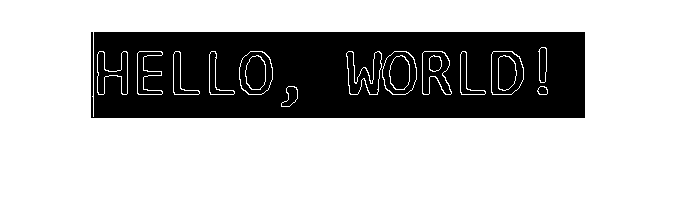

O=zeros(size(grayim));
O=uint8(O);
G1=zeros(size(grayim));
G1=uint8(G1);
G2=zeros(size(grayim));
G2=uint8(G2);
for i=1:size(grayim,1)-1
    for j=1:size(grayim,2)-1
        if(grayim(i,j)==~grayim(i,j+1))
            G1(i,j)=1;
        end
        if(grayim(i,j)==~grayim(i+1,j))
            G2(i,j)=1;
        end
        if(G1(i,j)||G2(i,j)==1)
            O(i,j)=1;
        end
    end
end
imshow(O,[0,1]);

6.label

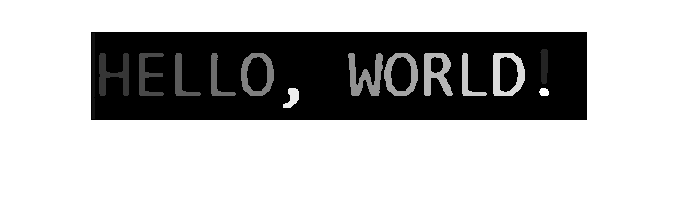

L= zeros(size(grayim));
L= uint8(L);
Ap = padarray(grayim,[1 1],0);%0 is background, 1 is object
L = padarray(L,[1 1],0);
Ap=1-Ap;        %negative

isSearched=zeros(size(L));
Lnb = 0;
label=0;
queue=[];
%  1,1  0,-1 1,-1
% -1,0       1,0
% -1,1  0,1  1,1
direction=[-1,0;-1,1;0,1;1,1;1,0;1,-1;0,-1;-1,-1];
for i=2:size(Ap,1)-1
    for j=2:size(Ap,2)-1
        if(Ap(i,j)==1)%is background
            continue;
        end
        if(Ap(i,j)==0 && L(i,j)==0)%is object and not searched
            label=label+1;
            L(i,j)=label;
            queue=[i;j];
            %%%%%%%%%%%%%%%BFS%%%%%%%%%%%%%%%%
            while size(queue)~=0
                center=[queue(1,1),queue(2,1)];
                queue(:,1)=[];%delete this center from queue
                for k = 1:8 
                    sround=center+direction(k,:);%sround is 1x2 matrix (i,j)
                    if(Ap(sround(1),sround(2))==0 && L(sround(1),sround(2))==0)%is objective and not searched
                        L(sround(1),sround(2))=label;%label this sround
                        queue = [queue,[sround(1);sround(2)]];%(sround1,sround2) as center
                    end
                end
            end
        end
    end
end
imshow(L,[0,label]);

7.K-NN

Input_path = 'D:\NUS\machine vision\p_dataset_26\SampleD\';  
%Output_path='D:\NUS\machine vision\p_dataset_26\test\';
namelist = dir(strcat(Input_path,'*.png'));  %获得文件夹下所有的 .jpg图片
len = length(namelist);
D_T=zeros(len,7);%D result (len,features)
for i = 1:len
    name=namelist(i).name;  %namelist(i).name; %这里获得的只是该路径下的文件名
    I=imread(strcat(Input_path, name)); %图片完整的路径名
    I(I<100)=0;
    I(I>=100)=1;
    %imshow(I,[0,1]);%grey
    
    %features
    
    %feature 1,2 crossing
    V=0;H=0;firstobject_flag=0;
    for l=1:size(I,1)
        for h=1:size(I,2)
            if(I(l,h)==0) %first object
                firstobject_flag=1;
                for l1=2:size(I,1)
                    if(I(l1-1,h)==1 && I(l1,h)==0)
                        V=V+1;
                    end
                end
                break;
            end
        end
        if(firstobject_flag==1)
            break;
        end
    end
    
    firstobject_flag=0;
    for h=1:size(I,2)
        for l=1:size(I,1)
            if(I(l,h)==0) %first object
                firstobject_flag=1;
                for h1=2:size(I,2)
                    if(I(l,h1-1)==1 && I(l,h1)==0)
                        H=H+1;
                    end
                end
                break;
            end
        end
        if(firstobject_flag==1)
            break;
        end
    end
    D_T(i,1)=V;
    D_T(i,2)=H;
    
    %feature 3 
    
    
    %feature 4
    
    
    

    
    
    
    %imwrite(K2,[Output_path,'wie',int2str(i),'.jpg']); %完整的图片存储的路径名  并将整形的数字 
                                                        
end
 

8.SVM

function y_predict = my_MultiSvm(X_train, y_train, X_test)
% multi svm
% one vs all 模型
% Input:
% X_train: n*m矩阵 n为训练集样本数 m为特征数
% y_train: n*1向量 为训练集label，支持任意多种类
% X_test: n*m矩阵 n为测试集样本数 m为特征数
% Output:
% y_predict: n*1向量 测试集的预测结果
% 
% 
    %
    y_labels = unique(y_train);
    n_class = size(y_labels, 1);
    models = cell(n_class, 1);
    % 训练n个模型
    for i = 1:n_class
        class_i_place = find(y_train == y_labels(i));
        svm_train_x = X_train(class_i_place,:);
        sample_num = numel(class_i_place);
        class_others = find(y_train ~= y_labels(i));
        randp = randperm(numel(class_others));
        svm_train_minus = randp(1:sample_num)';
        svm_train_x = [svm_train_x; X_train(svm_train_minus,:)];
        svm_train_y = [ones(sample_num, 1); -1*ones(sample_num, 1)];
        disp(['生成模型：', num2str(i)])
        models{i} = fitcsvm(svm_train_x, svm_train_y);
    end
    test_num = size(X_test, 1);
    y_predict = zeros(test_num, 1);
    % 对每条数据，n个模型分别进行预测，选择label为1且概率最大的一个作为预测类别
    for i = 1:test_num
        if mod(i, 100) == 0
            disp(['预测个数：', num2str(i)])
        end
        bagging = zeros(n_class, 1);
        for j = 1:n_class
            model = models{j};
            [label, rat] = predict(model, X_test(i,:));
            bagging(j) = bagging(j) + rat(2);
        end
        [maxn, maxp] = max(bagging);
        y_predict(i) = y_labels(maxp);
    end
end

xinde 8

% 
% 
% 
% Input_path = D:'\Documents\nus\5405-machine vision\project\p_dataset_26';  
% %Output_path='D:\NUS\machine vision\p_dataset_26\test\';
% namelist = dir(strcat(Input_path,'*.png'));  %获得文件夹下所有的 .jpg图片
% len = length(namelist)
% D_T=zeros(len,7);%D result (len,features)
% 
% 
% 
% % option = statset('MaxIter',1000000);
% % svm_struct = svmtrain(train_data_pca,train_label,'options',option);
% % predict = svmclassify(svm_struct,test_data_pca);
% % correct_num = sum((predict-test_label')==0);
% % accuracy = correct_num / 3000;



